%Parametre
clear all;
close all;
Ms=280;
Mu=45;
Ks=20000;
Kt=150000;
Cs=1000;
Ct=0.0;

A=[0 1 0 -1
    -Ks/Ms -Cs/Ms 0 Cs/Ms
    0 0 0 1
    Ks/Mu Cs/Mu -Kt/Mu -(Cs-Ct)/Mu];

B=[0
    1/Ms
    0
    -1/Mu];

E=[0
    0
    -1
    Ct/Mu];

D=0;

%Caisse
Cst=[0 1 0 0];
SysZs=ss(A,E,Cst,D);
Zs_Zr=tf(SysZs)

Zs_Zr =
 
                1.19e04 s + 2.381e05
  -------------------------------------------------
  s^4 + 25.79 s^3 + 3849 s^2 + 1.19e04 s + 2.381e05
 
Continuous-time transfer function.




Cut = [0 0 0 1];
SysZu=ss(A,E,Cut,D);
Zu_Zr=tf(SysZu)

Zu_Zr =
 
           3333 s^2 + 1.19e04 s + 2.381e05
  -------------------------------------------------
  s^4 + 25.79 s^3 + 3849 s^2 + 1.19e04 s + 2.381e05
 
Continuous-time transfer function.



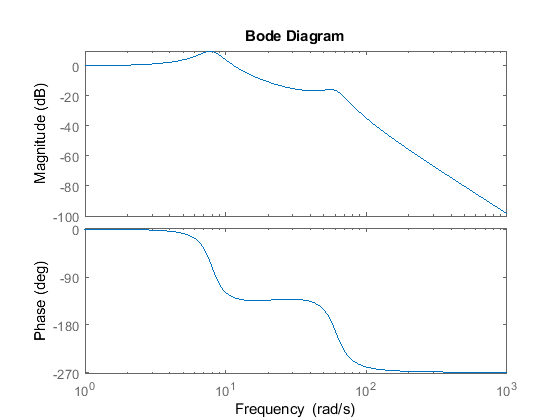


figure
bode(SysZs);

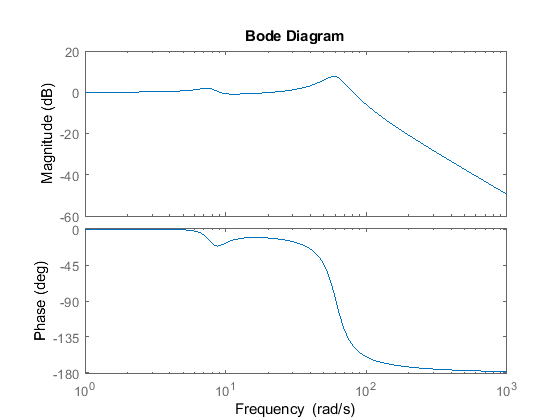

figure
bode(SysZu);

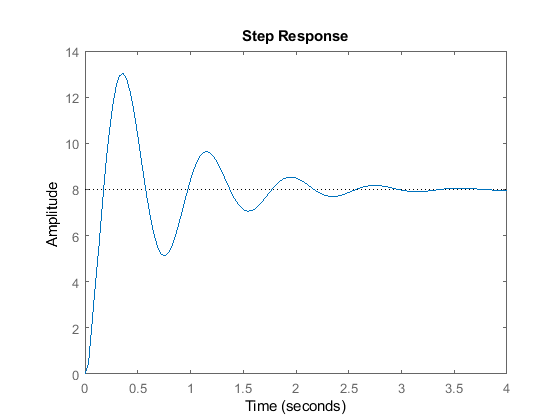


%Réponse temporelle
figure
sys = Zs_Zr*8;
step(sys);

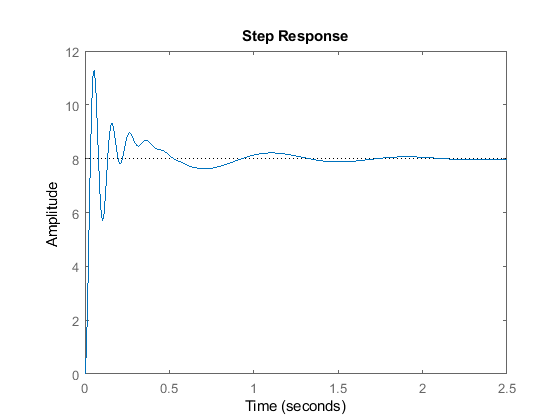

sys = Zu_Zr*8;
figure
step(sys);